## Estimation of Damping ratio from the Peak values of foamstar

The code will execute and estimate the damping ratios based on the peak amplitudes of Free decay!! 

disp("Estimation of damping coefficient...")

Estimation of damping coefficient...


### Load the Free Decay Time series data and show with the peak

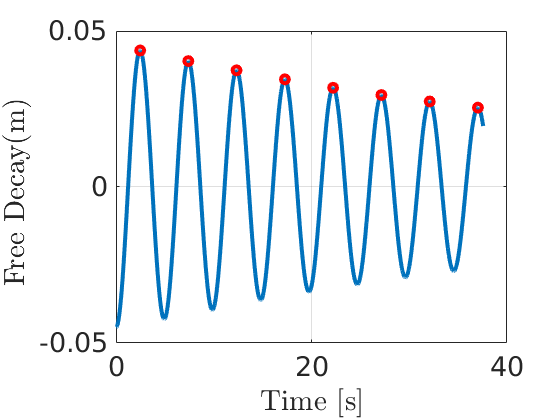

dof=3;
    foamStarfullfile=fullfile('/mnt/data2/saliyar/Spece_constraint/Files_from_LIGER/Floating_Body_Simulation/Revision1/FreeDecay/HeaveFD/Heave_ppcd35','/postProcessing/motionInfo/0/cylinder1.dat');
    data=readtable(foamStarfullfile); 
    dt_motion_foamstar=data{:,1}; % This number is case specific to be updated
    dof_foamstar=data{:,dof+1};
    dof_foamstar=dof_foamstar-0.045; % Initial amplitude
    [pks,locs] = findpeaks(dof_foamstar,'MinPeakHeight',0.0075,'MinPeakDistance',200);
 
    figure()
    plot(dt_motion_foamstar,dof_foamstar,dt_motion_foamstar(locs),pks,'or','LineWidth',3)
    xlim([0 40])
    ylabel('Free Decay(m) ','interpreter','latex','FontSize',20)
    xlabel('Time [s]','interpreter','latex','FontSize',20)
    set(gca,'Fontsize',20)
    grid on;

### Thoery 

The damping coefficient were determined using logarithmic decremented method :

                                                
$$ \delta= \frac{1}{n} ln \bigg( \frac{x_0}{x_n}\bigg)$$


The damping ratio is then found from the logarithmic decrement.

                                            
$$ \zeta = \frac{1}{\sqrt{1+ \big(\frac{2 \pi}{\delta}\big)^2}}$$


### Estimation of Damping ratio

In general moslty 4 peaks is the maximum 

Pick the First amplitude (From first 3 peaks) 

    first_amplitude=1;
    fprintf('The first amplitude chosen : %d \n',first_amplitude);

The first amplitude chosen : 1 


    
    x0=pks(first_amplitude);
    fprintf('The first amplitude value : %f \n',x0);

The first amplitude value : 0.043767 


 Number of peaks 

NumberOfPeaks=8;
fprintf('The number of peaks chosen : %d \n',NumberOfPeaks);

The number of peaks chosen : 8 


xn=pks(NumberOfPeaks);
fprintf('The Chosen amplitude value : %f \n',xn);

The Chosen amplitude value : 0.025434 



delta=(1/(NumberOfPeaks-1)) * log(x0/xn);
fprintf('The logarithmic decrement  : %f \n',delta);

The logarithmic decrement  : 0.077543 



constant=(2*pi/delta)^2;
DampingCoefficient = (1/(sqrt(1+constant)))*100;
fprintf('The Damping Coefficient  : %f %% \n',DampingCoefficient);

The Damping Coefficient  : 1.234044 % 
